# Asteroid - Gauss

## Problema

Un asteroid ce orbitează în jurul Soarelui a putut � observat timp de câteva zile înainte să dispară. Iată 10 observații

close all
x=[-1.024940; -0.949898; -0.866114; -0.773392; -0.671372; -0.559524;...	
    -0.437067; -0.302909; -0.159493; -0.007464];
y=[-0.389269; -0.322894; -0.265256;	-0.216557;	-0.177152; -0.147582;...
    -0.128618; -0.121353;	-0.127348; -0.148895];

Se dorește calcularea traiectoriei pe baza acestor observații pentru a putea prevedea situația când orbita va � din nou vizibilă. Se știe că orbita este o conică:


$$\alpha x^2+\beta xy +\gamma y^2+\delta x +\varepsilon y+\mu=0$$


Vrem să știm dacă este periodică (corpul va reveni, orbită eliptică) sau nu (orbită hiperbolică sau parabolică). 

## Modelul eliptic

Să alegem un model eliptic pentru orbită (împărțim cu coeficientul lui $$x^2$$ și redenumim variabilele)

$ay^2+bxy+cx+dy+e=x^2$.

El ne conduce la un sistem supradeterminat pe care îl rezolvăm în sensul celor mai mici pătrate

A=[y.^2, x.*y, x, y, ones(size(x))];
bv=x.^2;
coef=A\bv;
a=coef(1); b=coef(2); c=coef(3); d=coef(4); e=coef(5);

Vizualizare

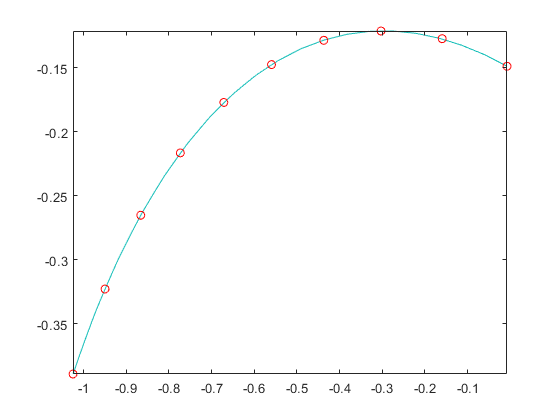

u=linspace(min(x),max(x),20);
v=linspace(min(y),max(y),20);
[X,Y]=meshgrid(u,v);
Z=a*Y.^2+b*X.*Y+c*X+d*Y+e-X.^2;
contour(X,Y,Z,[0,0]); hold on
plot(x,y,'ro'); hold on

Alegem o altă fereastră $[-2,2]\times[-3,0]$

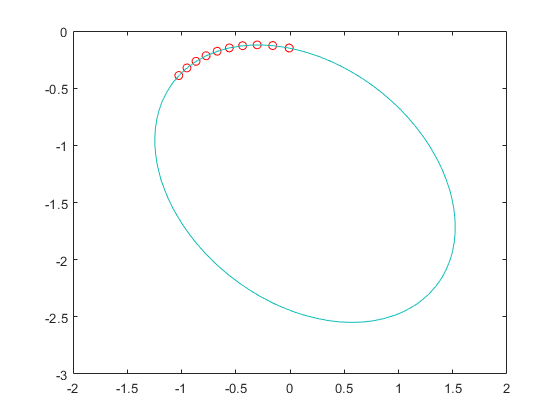

figure()
plot(x,y,'ro'); hold on
u=linspace(-2,2,40);
v=linspace(-3,0,40);
[X,Y]=meshgrid(u,v);
Z=a*Y.^2+b*X.*Y+c*X+d*Y+e-X.^2;
contour(X,Y,Z,[0,0]); 

## Eroarea în modelul eliptic

Eroarea este norma diferenței dintre poziția observată și cea calculată

err=sum((a*y.^2+b*x.*y+c*x+d*y+e-x.^2).^2).^(1/2)

err =        0.00109838436433489


errb=norm(a*y.^2+b*x.*y+c*x+d*y+e-x.^2)

errb =        0.00109838436433489


## Modelul parabolic

Facem același lucru pentru modelul parabolic


$$ay+e=x^2$$


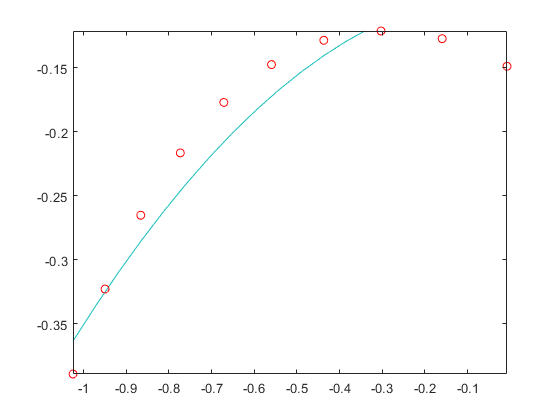

figure()
A2=[y,ones(size(x))];
coef2=A2\bv;
a=coef2(1); e=coef2(2);
u=linspace(min(x),max(x),20);
v=linspace(min(y),max(y),20);
[X,Y]=meshgrid(u,v);
Z=a*Y+e-X.^2;
contour(X,Y,Z,[0,0]); hold on
plot(x,y,'ro')

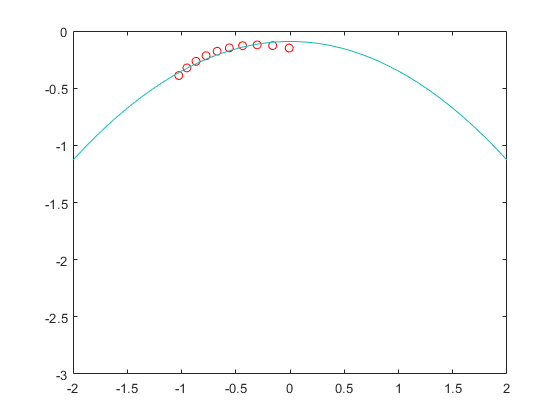

figure()
plot(x,y,'ro'); hold on
u=linspace(-2,2,40);
v=linspace(-3,0,40);
[X,Y]=meshgrid(u,v);
Z=a*Y+e-X.^2;
contour(X,Y,Z,[0,0]);

## Eroarea în modelul parabolic

err2=sum((a*y+e-x.^2).^2)^(1/2)

err2 =          0.343340386341414


err2b=norm(a*y+e-x.^2)

err2b =          0.343340386341414


Se observă că modelul eliptic este mai probabil (are eroarea mai mică)